# Sistem

A = [0 1 0; 0 0 1; -1 -3 -3];   %Matrica dinamike stanja
B = [0; 0; 1];                  %Matrica ulaza
C = [1, 0, 0];                    %Matrica izlaza
D = 0;                          %Matrica direktnog prenosa


T = 1e-3;
ic = 0;

## Sim - Estimacija stanja i poremecaja. Step. Ukoliko je omega = 0 -> spec. slucaj za step i rampu.

Model prostoperiodicnog poremecaja sa ucetanoscu $\omega$ mozemo zapisati kao diferencijalnu jednacinu drugog reda kroz izraz

$\ddot{d}(t) + \omega d(t) = 0$. 

Smenom promenljivih $w_1 = d(t)$ i $w_2 = \dot{d}(t)$ dobijamo linearni sistem diferencijalnih jednacina


$$\dot{w}_1(t) = w_2, \\
\dot{w}_2(t)  = - \omega^2 w_1, \\
d(t)  = w_1 $$
 

odnosno u matricnom obliku kao

 $\dot{w} = A_w w \\
d = C_w w$.

Ukoliko uzmemo da je $\omega = 0$ tada prethodne diferencijalne jednacine opisuju linearno rastuci odnosno poremecaj oblika $d(t) = at + b$.

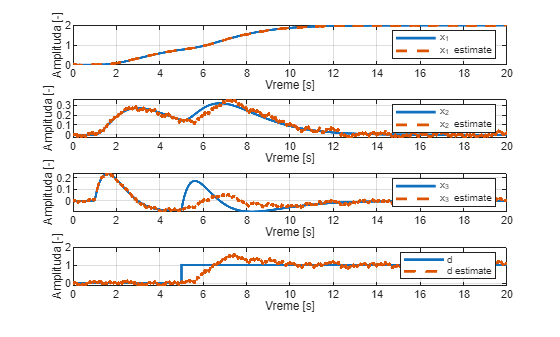

close all;
omega = 0 *2 * pi;
Aw = [0, 1; -omega^2, 0 ];
Cw = [1, 0];
Ae = [A, B*Cw; zeros([length(Aw), length(A)]), Aw];
Ce = [C zeros(size(Cw))];
L = acker(transpose(Ae), transpose(Ce),  -2 * [1 , 1, 1, 1, 1]);

[y, dest, d, xhat, x, t] = simulate(1, 1, 1, "step");
t = t(1:length(xhat));

subplot(4, 1, 1);
plot(t, x(1, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_1"); hold on;
plot(t, xhat(1, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_1 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 2);
plot(t, x(2, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_2"); hold on;
plot(t, xhat(2, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_2 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 3);
plot(t, x(3, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_3"); hold on;
plot(t, xhat(3, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_3 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 4);
plot(t, d(1:length(dest)), "LineWidth", 2, "LineStyle","-", "DisplayName", "d"); hold on;
plot(t, dest, "LineWidth", 2, "LineStyle","--", "DisplayName", "d estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

## Sim - Estimacija stanja i poremecaja. Rampa

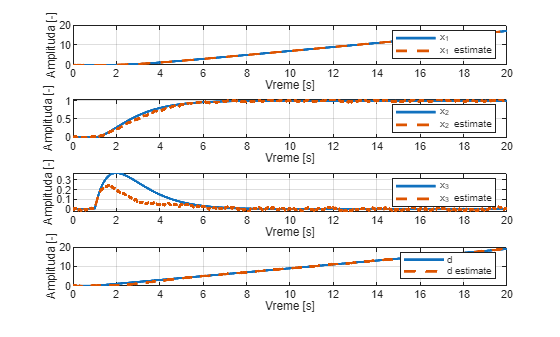

close all;
omega = 0 *2 * pi;
Aw = [0, 1; -omega^2, 0 ];
Cw = [1, 0];
Ae = [A, B*Cw; zeros([length(Aw), length(A)]), Aw];
Ce = [C zeros(size(Cw))];
L = acker(transpose(Ae), transpose(Ce),  -2 * [1 , 1, 1, 1, 1]);

[y, dest, d, xhat, x, t] = simulate(1, 1, 1, "ramp");
t = t(1:length(xhat));

subplot(4, 1, 1);
plot(t, x(1, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_1"); hold on;
plot(t, xhat(1, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_1 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 2);
plot(t, x(2, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_2"); hold on;
plot(t, xhat(2, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_2 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 3);
plot(t, x(3, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_3"); hold on;
plot(t, xhat(3, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_3 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 4);
plot(t, d(1:length(dest)), "LineWidth", 2, "LineStyle","-", "DisplayName", "d"); hold on;
plot(t, dest, "LineWidth", 2, "LineStyle","--", "DisplayName", "d estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

## Sim - Estimacija stanja i poremecaja. Prostoperiodican poremecaj

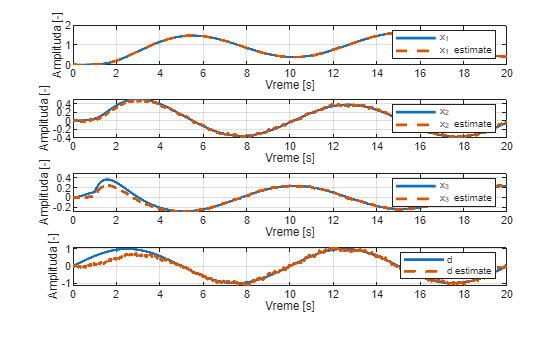

close all;
omega = 0.1 *2 * pi;
Aw = [0, 1; -omega^2, 0 ];
Cw = [1, 0];
Ae = [A, B*Cw; zeros([length(Aw), length(A)]), Aw];
Ce = [C zeros(size(Cw))];
L = acker(transpose(Ae), transpose(Ce),  -2 * [1 , 1, 1, 1, 1]);

[y, dest, d, xhat, x, t] = simulate(1, 1, 1, "sine");
t = t(1:length(xhat));

subplot(4, 1, 1);
plot(t, x(1, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_1"); hold on;
plot(t, xhat(1, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_1 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 2);
plot(t, x(2, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_2"); hold on;
plot(t, xhat(2, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_2 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 3);
plot(t, x(3, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_3"); hold on;
plot(t, xhat(3, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_3 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 4);
plot(t, d(1:length(dest)), "LineWidth", 2, "LineStyle","-", "DisplayName", "d"); hold on;
plot(t, dest, "LineWidth", 2, "LineStyle","--", "DisplayName", "d estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

## Sim - Estimacija stanja i poremecaja. Step + prostoperiodicnog poremecaj

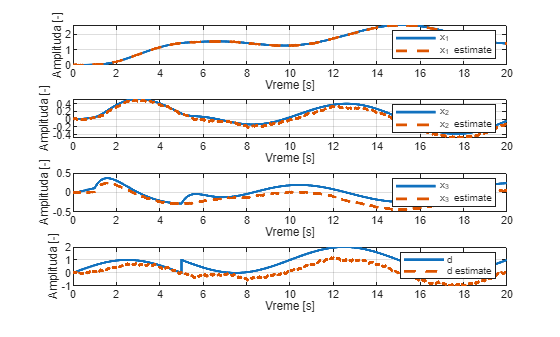

close all;
omega = 0.1 *2 * pi;
Aw = [0, 1; -omega^2, 0 ];
Cw = [1, 0];
Ae = [A, B*Cw; zeros([length(Aw), length(A)]), Aw];
Ce = [C zeros(size(Cw))];
L = acker(transpose(Ae), transpose(Ce),  -2 * [1 , 1, 1, 1, 1]);

[y, dest, d, xhat, x, t] = simulate(1, 1, 1, "mixed");
t = t(1:length(xhat));

subplot(4, 1, 1);
plot(t, x(1, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_1"); hold on;
plot(t, xhat(1, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_1 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 2);
plot(t, x(2, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_2"); hold on;
plot(t, xhat(2, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_2 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 3);
plot(t, x(3, 1:length(xhat)), "LineWidth", 2, "LineStyle","-", "DisplayName", "x_3"); hold on;
plot(t, xhat(3, :), "LineWidth", 2, "LineStyle","--", "DisplayName", "x_3 estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

subplot(4, 1, 4);
plot(t, d(1:length(dest)), "LineWidth", 2, "LineStyle","-", "DisplayName", "d"); hold on;
plot(t, dest, "LineWidth", 2, "LineStyle","--", "DisplayName", "d estimate");
xlabel("Vreme [s]");ylabel("Amplituda [-]");grid on; legend show; 

## Sim. func.

function [y, dest, d, xhat, x, t] = simulate(R0, D0, noise, d_type)
   mdl = "state_estim_mdl";
   switch(d_type)
       case "sine"
           set_param(mdl + "/sine", "Gain", num2str(1));
           set_param(mdl + "/ramp", "Gain", num2str(0));
           set_param(mdl + "/step", "Gain", num2str(0));
       case "ramp"
           set_param(mdl + "/sine", "Gain", num2str(0));
           set_param(mdl + "/ramp", "Gain", num2str(1));
           set_param(mdl + "/step", "Gain", num2str(0));
       case "step"
           set_param(mdl + "/sine", "Gain", num2str(0));
           set_param(mdl + "/ramp", "Gain", num2str(0));
           set_param(mdl + "/step", "Gain", num2str(1));
       case "mixed"
           set_param(mdl + "/sine", "Gain", num2str(1));
           set_param(mdl + "/ramp", "Gain", num2str(0));
           set_param(mdl + "/step", "Gain", num2str(2));           
   end

    %open_system(mdl);
    set_param(mdl + "/r", "After", num2str(R0));
    set_param(mdl + "/d", "Gain", num2str(D0));
    set_param(mdl + "/Gain", "Gain", num2str(noise))
    out = sim(mdl);

    y = transpose(squeeze(out.y(1,:, :)));
    x = transpose(squeeze(out.x));
    xhat = transpose(squeeze(out.xhat));
    dest = squeeze(out.dest);
    d = out.d;
    t = out.tout(:, 1);
    
end